## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from PDE model with Reflecting boundaries |x|<=a.

This scrip just changing para by hand and make the frame of simulation.

## fv1 Intro

In this scrip, we try to adjust para automatically. First we use **gradient descent**. 

## fv5 Intro

In this scrip, we adapt GD into steepest descent.

## Import data and previewing

The data come from expomential fitness data.

data_name='n78';
selecting_curve='xy';
experiment_interval=5;
min_length=51;
time_scale=experiment_interval*(1:min_length);

fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=1.906e+05;%n142_5s
a(2)=0.0008269;
a(3)=-1.448e+05;
a(4)=-0.02463;


Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);


## Parameter importing

input=[9.80574346042647e-07	,0.541565565789399	,1.05125973173442e-14];
a=input(1);%m
Gamma=input(2);
K_gamma=input(3);

% decide step length and sample length (proportional)

step_length=1/100;
sample_length=1/10000;

## storage system

% add parameter history and gradient history
parameter_history=[a,Gamma,K_gamma];
gradient_history=[];
residual_history=[];

## Main loop

for step_number=1:100
    residual_0=FDE_get_residual(interceptive_experiment_MSD,a,Gamma,K_gamma,experiment_interval,min_length);
    residual_a=FDE_get_residual(interceptive_experiment_MSD,a*(1+sample_length),Gamma,K_gamma,experiment_interval,min_length);
    residual_Gamma=FDE_get_residual(interceptive_experiment_MSD,a,Gamma*(1+sample_length),K_gamma,experiment_interval,min_length);
    residual_K=FDE_get_residual(interceptive_experiment_MSD,a,Gamma,K_gamma*(1+sample_length),experiment_interval,min_length);
    gradient=[residual_a-residual_0,residual_Gamma-residual_0,residual_K-residual_0]/sample_length;
    unit_gradient=gradient/norm(gradient);
    if step_number==1
        standard_gradient=norm(gradient);
    end
    
    %por=norm(gradient)/standard_gradient;
    por=residual_0/norm(gradient);
    a=a*(1-unit_gradient(1)*step_length*por);
    Gamma=Gamma*(1-unit_gradient(2)*step_length*por);
    K_gamma=K_gamma*(1-unit_gradient(3)*step_length*por);
    
    parameter_history=[parameter_history;[a,Gamma,K_gamma]];
    gradient_history=[gradient_history;gradient];
    residual_history=[residual_history;residual_0];
end

## saving

saving data

%saving_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.02图像';
%save([saving_location,'\data\history data N=',num2str(Total_experiment_number),' step=',num2str(step_length),datestr(now,' yyyy-mm-dd HH'),'.mat'],'parameter_history','gradient_history','residual_history')

Plot and plot saving: gradient history

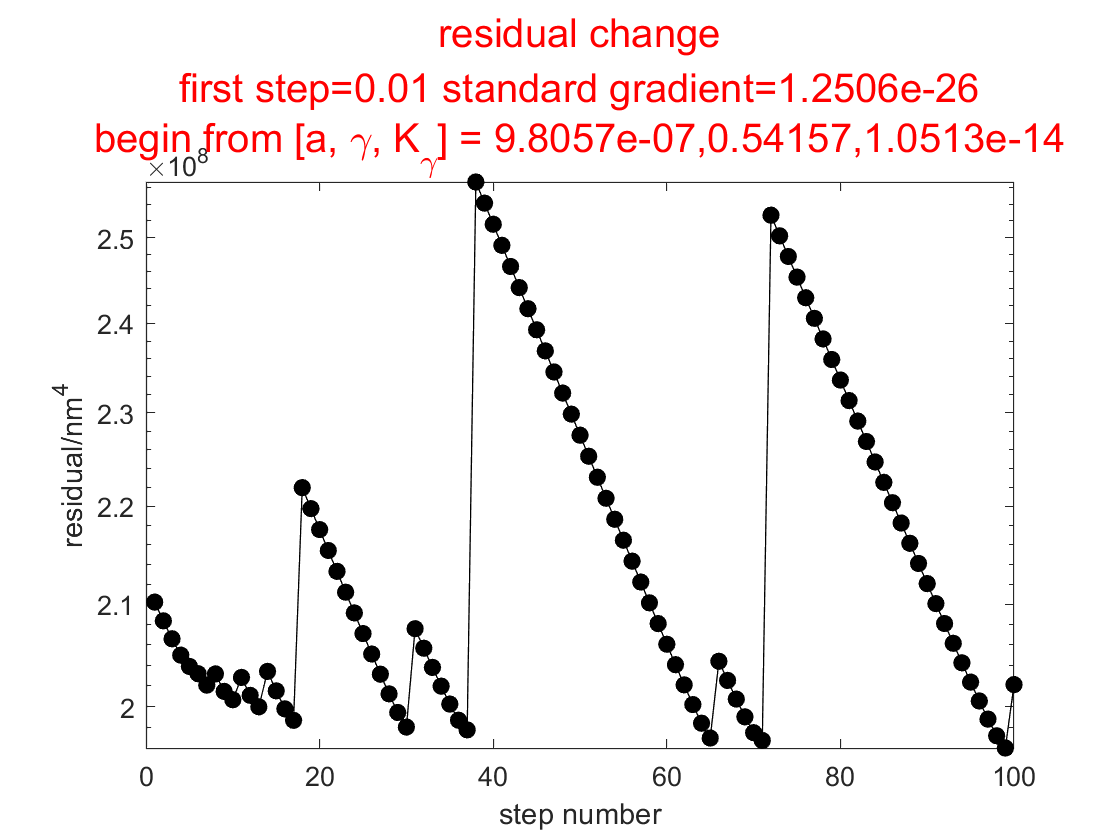

figure
plot((residual_history(:,1))*1e36,'k-o','MarkerFaceColor','k')
xlabel('step number')
ylabel('residual/nm^4')
set(gca,'yscale','log');
title({'residual change',['first step=',num2str(step_length),' standard gradient=',num2str(standard_gradient)],['begin from [a, \gamma, K_\gamma] = ',num2str(input(1)),',',num2str(input(2)),',',num2str(input(3))]},'Color','r','FontSize',15)

plot MSD

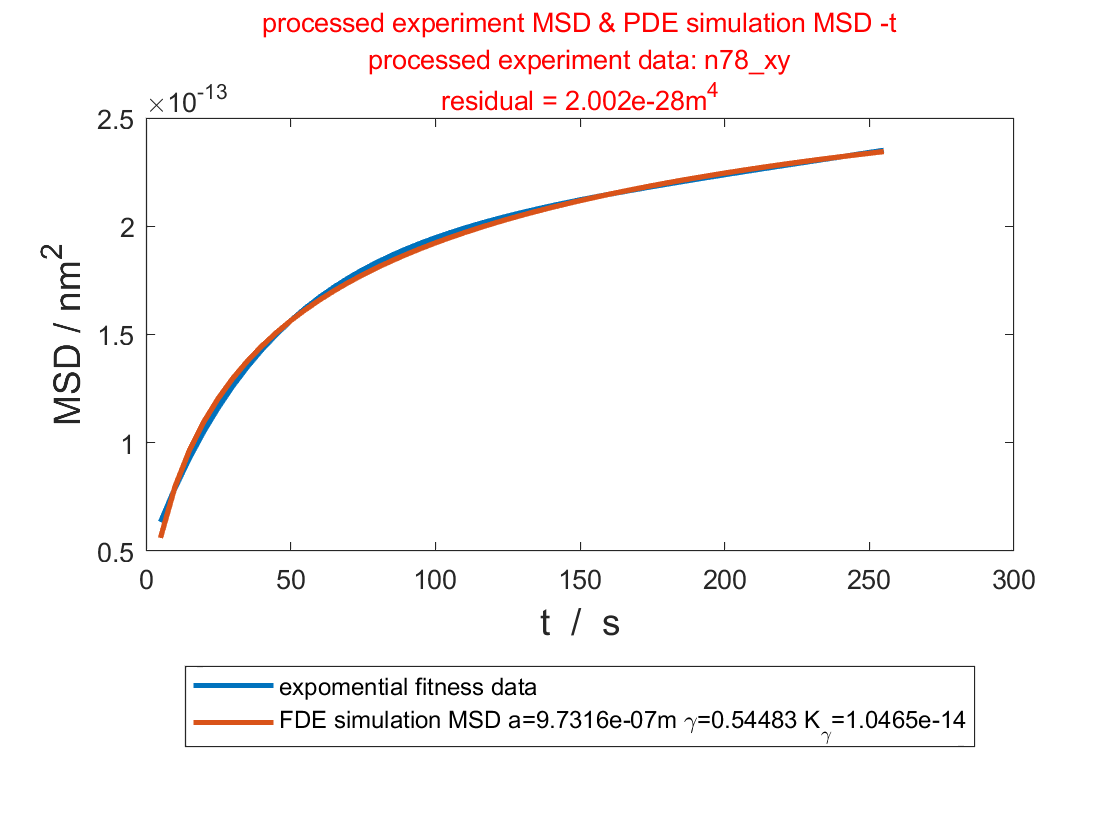

a=parameter_history(end,1);%m
Gamma=parameter_history(end,2);
K_gamma=parameter_history(end,3);


simulation_MSD=[];
for t=experiment_interval*[1:min_length]
    sum_number=10;
    sum_list=zeros(sum_number,1);
    for m=1:sum_number
        sum_list(m)=((-1)^m/m^2)*mlf(Gamma,1,-K_gamma*m^2*pi^2/a^2*t^Gamma,6);
    end
    simulation_MSD=[simulation_MSD,a^2*(1/3+4/pi^2*sum(sum_list))];
end
residual=sum((interceptive_experiment_MSD-simulation_MSD).^2);

figure
plot(time_scale,interceptive_experiment_MSD,"LineWidth",2,'displayname','expomential fitness data')
hold on
legend_name=strcat('FDE simulation MSD',' a= ',num2str(a),'m \gamma=',num2str(Gamma),' K_\gamma= ',num2str(K_gamma));
plot(time_scale,simulation_MSD,"LineWidth",2,'displayname',legend_name)
xlabel('t  /  s','FontSize',14);
ylabel('MSD / nm^2','FontSize',14);
title({['processed experiment MSD & PDE simulation MSD -t'],['processed experiment data: ',strrep(data_name,'_','\_'),'\_',selecting_curve],['residual = ',num2str(residual),'m^4']},'Color','r','FontSize',10);
legend('Location','southoutside');